# Killeen's p-rep (probability of replication)

Formulas from:

Bruno Lecoutre, Marie-Paule Lecoutre, Jacques Poitevineau.  Killeen’s Probability of Replication and Predictive Probabilities:  How to Compute, Use, and Interpret Them.  Psychological Methods, American Psychological Association, 2010, 15 (2), pp.158-171. 10.1037/a0015915. hal-00491698

See also:

[An alternative to null-hypothesis significance tests](https://scholar.google.com/citations?view_op=view_citation&hl=en&user=HvJEyMcAAAAJ&citation_for_view=HvJEyMcAAAAJ:u-x6o8ySG0sC)

PR Killeen, Psychological science 16 (5), 345-353

[Predict, control, and replicate to understand: How statistics can foster the fundamental goals of science](https://scholar.google.com/citations?view_op=view_citation&hl=en&user=HvJEyMcAAAAJ&sortby=pubdate&citation_for_view=HvJEyMcAAAAJ:6H908wyzF9cC)

PR Killeen, Perspectives on Behavior Science 42 (1), 109-132

**Critiques of accuracy of p-rep:**

[https://pubmed.ncbi.nlm.nih.gov/20822254/](https://pubmed.ncbi.nlm.nih.gov/20822254/)

What is the probability of replicating a statistically significant effect? Jeff Miller

[https://link.springer.com/content/pdf/10.3758/PBR.16.4.617.pdf](https://link.springer.com/content/pdf/10.3758/PBR.16.4.617.pdf)

*p*rep misestimates the probability of replication

[https://link.springer.com/article/10.3758/PBR.16.2.424](https://link.springer.com/article/10.3758/PBR.16.2.424)

**p_rep** is the probability of a replication sample obtaining an effect of the same sign (no sign error).

**ps_rep** is the probability of obtaining a significant result in a replication sample at a given significance level (alpha, e.g., alpha = 0.05 yields significance at p < 0.05).  

p_rep_from_p = @(p) normcdf(norminv(1 - p) ./ sqrt(2)); % Lecoutre 2010, known variance case, Eq. 1; 1-tailed P-value

% ps_rep: Known variance case, Eq. 1
% Enter 2-tailed P-value for first test/sample, 
% and assume we want 2-tailed p-values for the replication

ps_rep_from_p_2t = @(p, alpha) normcdf(norminv(1 - p ./ 2) ./ sqrt(2) - norminv(1 - alpha ./ 2) ./ sqrt(2)); 


Because p_rep is the probability of a replication sample obtaining an effect of the same sign, p_rep with no effect (t = 0) is 0.5, regardless of the sample size.

p_rep(0, 9)

ans = 0.5000

p_rep(0, 1000)

ans = 0.5000

*"The  derivation  of  prep  and  psrep  when  s  is  unknown  is  a  straightforward  extension  of  the  known s case, the normal distribution being replaced with new distributions. Let t_rep denote the t test  statistic  in  the  replication  and  let  t_obs  be  its  observed  value  in  the  first  experiment.  In  this  case,  we  have  to  consider  the  probability  that  t_rep  exceeds  a  specified  value for  each  possible  value of (m,s). On  the  one  hand,  the  sampling  distribution  of t_rep  is  a noncentral t  distribution  with n df  (as  the  t  test)  and  noncentrality  parameter  m/(s/ n ),  noted  t'(v)(m/(s/ n ).  This  distribution  is  familiar  to  power  analysts  and  confidence  intervals  users  (see,  e.g.,  Cumming  &  Finch,  2001;  Lecoutre, 2007). On the other hand, the fiducial Bayesian distribution of m/(s/ n ) is a lambda- prime distribution with n df and noncentrality parameter equal to  the observed value tobs = 1.10,  noted L '(n)(tobs).  This  distribution,  which  was  considered  (with  no  name)  by  Fisher  (1990/1973,  pp.  126-127)  in  the  fiducial  framework, was  called  lambda-prime  in  Lecoutre  (1999)  (see  also  Rouanet & Lecoutre, 1983 and  Lecoutre, 2007)."*

*"p_rep  can  be  very  easily  computed  in  the  unknown  variance  case,  the  normal  distribution  being  simply  replaced  with  the t  distribution.  This  is  coherent  with  the  fact  that  the  predictive  distribution  of  the mean difference xrep is a t distribution."*

p_rep = @(t, df) tcdf(abs(t)/sqrt(2),df);  % Lecoutre 2010, unknown variance case, Eq. 13


ps_rep = @(t, df, alpha) tcdf(abs(t)/sqrt(2) - tinv(1 - alpha ./ 2, df)/sqrt(2), df);  % Lecoutre 2010, unknown variance case, Eq. 13


## Example from Lecoutre paper

*The  following  example  (called  CC  example)  will  serve  us  for  illustration  throughout  the  paper. Conway  and  Christiansen  (2006)  considered  the  mean  of  the  n=10  paired differences  between  an  experimental  group  and  its  baseline.*

*For  the  auditory  modality,  they  reported  the  results  t(9) = 1.10, p = .30,  prep = .76,  d = .35,  where  p  is  the two-tailed p-value  and  d  is  the  standardized  mean  difference  (Cohen's  d).  From  their  Table 1,  it  can  be  inferred  that the  unstandardized  mean  difference  is  5.0.  *

*We  will  take  5.0  and  p = .30 as  the  exact  values  for  computations  (hence s = 14.3777...  and t = 1.0997...).  Note  that  we  have  deliberately  chosen  a nonsignificant  example,  because  it  is  particularly  important  to  alert  readers  to  the  fact  that  a  nonsignificant  result  cannot  be  interpreted  as  “proof  of  no  effect”,  or even  as  “proof  of  a  small  effect”.*

Here, df = 9 from 10 observations

p = 0.30 two-tailed is equal to 0.15 one-tailed

*"It  is  a  normal  distribution centered  on  zobs = xobs/(s/ n ) = 1.036,  with  unit  standard  deviation. The  resulting  average  values  are prep = .768  and psrep(.05) = .257,  given  by  the  predictive  distribution  of  zrep,  a  normal  distribution also centered on 1.036 and with standard deviation  sqrt(2) ."*

Note: I believe sqrt(2) comes from the fact that we are combining an initial and replication sample whose N(0, 1) distributions have variances that sum, yielding a standard deviation (sqrt of variance) of sqrt(1 + 1)

% Known variance case:
p_rep_from_p(0.3 / 2)         % enter 1-tailed P-value

ans = 0.7682

ps_rep_from_p_2t(0.3, 0.05)   % enter 2-tailed P-values

ans = 0.2569


% Unknown variance case: 
% "The  resulting  average  values  are  prep = .772  and  psrep(.05) = .230." 
p_rep(1.0997, 9)

ans = 0.7716

ps_rep(1.10, 9, 0.05)  % note: i get slightly different values here from the paper

ans = 0.2162

r2t = @(r, n) (r.*sqrt(n-2))./(sqrt(1-r.^2));

r2 = 0.01;
n = 1000;
tobs = r2t(sqrt(r2), n)

tobs = 3.1750


ps_rep(tobs, 1000 - 2, 0.05)

ans = 0.8600


r2psrep = @(r, n) ps_rep(r2t(r, n), n - 2, 0.05); % For 0.05 two-tailed  

% sample size needed
for i = 1:1000
    psrep_val(i) = r2psrep(sqrt(r2), i);
end

figure; hold on;
plot(psrep_val)

% minimum number for 80% power
n_vals = find(psrep_val > 0.8); n_vals = n_vals(1)

n_vals = 800


r2 = 0.02;

% sample size needed
for i = 1:1000
    psrep_val(i) = r2psrep(sqrt(r2), i);
end

hold on;
plot(psrep_val)

% minimum number for 80% power
n_vals = find(psrep_val > 0.8); n_vals = n_vals(1)

n_vals = 398

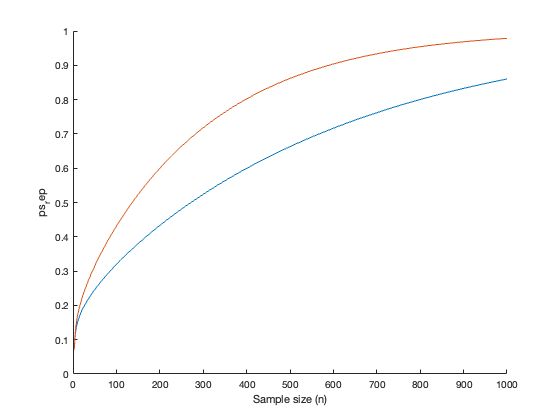


xlabel('Sample size (n)')
ylabel('ps_rep')